# **Passive Microwave Retrievals of Precipitation: A Regression or a Classification Problem?**

**Ardeshir Ebtehaj and Reyhaneh Rahimi**

**Univbersity of Minnesota **

**May 2023 (V0)**

## Abstract 

This paper demonstrates that recasting the satellite passive microwave retrievals of precipitation through classification neural networks, with cross-entropy loss function can increase the precision in the detection of precipitation occurrence and phase, by more than 10%, compared to the commonly used regression-based networks that rely on the mean-squared loss function. To that end, the coincidences of passive and active observations from the precipitation radiometer and radar onboard the Global Precipitation Measuring satellite are used. Embedding a classic Bayesian estimator in the feature space of a neural network, equipped with the focal-loss function, we demonstrate that the network can learn the positively skewed distribution of precipitation for improved retrieval of its extreme rates in terms of the critical success index.

## 1- Histogram of the Data

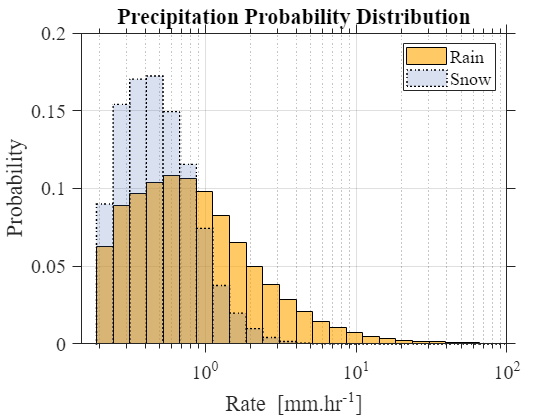

clear
load Dic_DPR_ocean_small.mat
nbins = 30;
edges = logspace(log10(0.19),log10(300),nbins);

Rain_c = discretize(data.train.Rate(data.train.Phase=="rain"),edges);
Snow_c = discretize(data.train.Rate(data.train.Phase=="snow"),edges);
figure()
histogram(data.train.Rate(data.train.Phase=="rain"),edges,'Normalization','probability','FaceColor',[255, 165, 0]./255)
set(gca,'xscale','log','TickDir','out','fontsize',15,'FontName','Times New Roman','TickLength',[0.02 0.02])
grid on 
xlim([0.15 100])
hold on
histogram(data.train.Rate(data.train.Phase=="snow"),edges,'Normalization','probability','FaceAlpha',0.2,'FaceColor',[66 103 178]./255,'LineStyle',':','LineWidth',1)
legend('Rain','Snow')
title('Precipitation Probability Distribution')
xlabel('Rate [mm.hr^{-1}]');
ylabel('Probability')

RainStat.mean = mean(data.train.Rate(data.train.Phase=="rain"));
RainStat.median  = median(data.train.Rate(data.train.Phase=="rain"));
RainStat.mode = mode(data.train.Rate(data.train.Phase=="rain"));
RainStat.p99  = prctile(data.train.Rate(data.train.Phase=="rain"),99.9)

RainStat = struct with fields:
      mean: 1.6960
    median: 0.7411
      mode: 0.2546
       p99: 67.5731


SnowStat.mean = mean(data.train.Rate(data.train.Phase=="snow"));
SnowStat.median = median(data.train.Rate(data.train.Phase=="snow"));
SnowStat.mode= mode(data.train.Rate(data.train.Phase=="snow"));
SnowStat.p99= prctile(data.train.Rate(data.train.Phase=="snow"),99.9)

SnowStat = struct with fields:
      mean: 0.5757
    median: 0.4616
      mode: 0.2562
       p99: 3.8520


## 2- Classification of Precipitation Types Using MLP

clear
load Dic_DPR_ocean_small.mat
data.train

ans = 600000×21 table
    TB10v     TB10h     TB18v     TB18h     TB23v     TB37v     TB37h     TB89v     TB89h     TB166v    TB166h    TB183v    TB183h      LWP         IWP       T2m       WVP         CAPE        Phase      Rate      Precip_type 
    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ________    ___

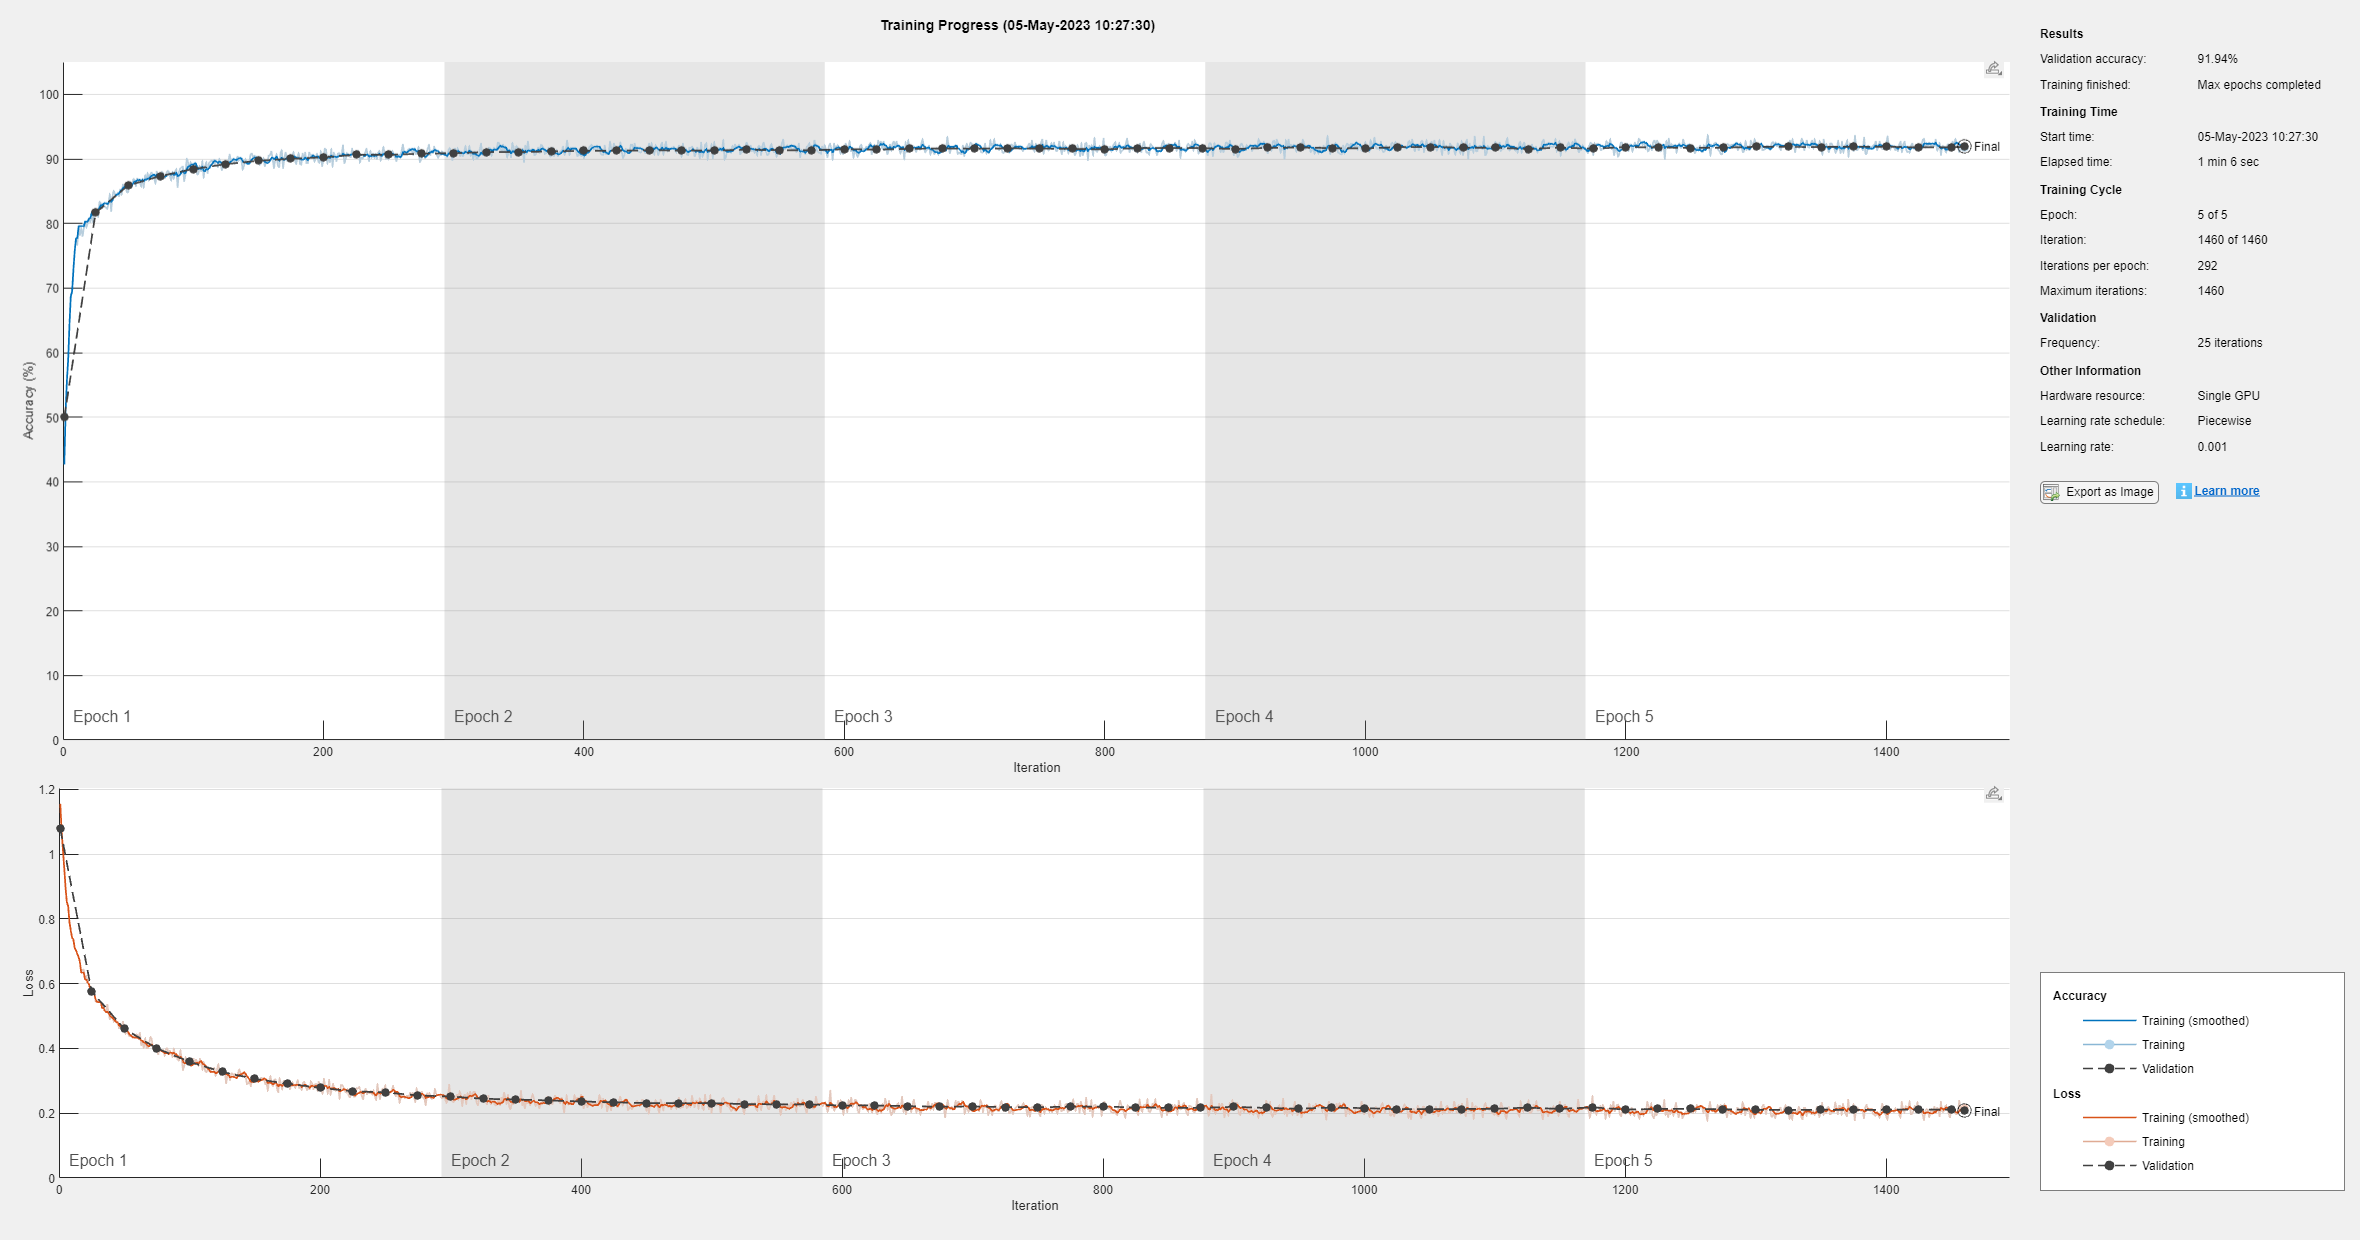

Inputs = ["TB10v","TB10h","TB18v","TB18h","TB23v","TB37v","TB37h",....
          "TB89v","TB89h","TB166v","TB166h","TB183v","TB183h",...
          "LWP","IWP","T2m","WVP","CAPE"];

X_train =  data.train(:,Inputs);
X_train =  table2array(X_train);

Y_train = categorical(data.train.Phase);

X_val   =  data.val(:,Inputs);
X_val   =  table2array(X_val); 
Y_val   = categorical(data.val.Phase);

X_test  =  data.test(:,Inputs);
X_test  = table2array(X_test);
Y_test  = categorical(data.test.Phase);

numClasses = 3;
net_CE = MLP_PMW_CE(numClasses,X_train,Y_train,X_val,Y_val);

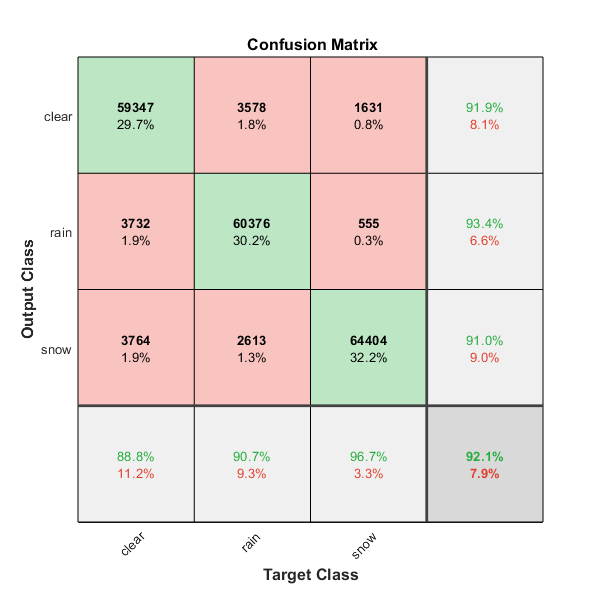

YPredTest = classify(net_CE,X_test);
plotconfusion(Y_test,YPredTest)

save('net_mcls_CE.mat','net_CE')

## 3- Reterievals using a Regression MSE Cost Function for Detection + Estimation

% detection and estimation by two networks. 
clear
load Dic_DPR_ocean_small.mat
Inputs = ["TB10v","TB10h","TB18v","TB18h","TB23v","TB37v","TB37h",....
          "TB89v","TB89h","TB166v","TB166h","TB183v","TB183h",...
          "LWP","IWP","T2m","WVP","CAPE"];

X_train   =  data.train(:,Inputs);
X_train   =  table2array(X_train);
Y_train_r = data.train.Rate;  Y_train_r(data.train.Phase=="snow")=0;  % setting the snowfall rates to zero
Y_train_s = data.train.Rate;  Y_train_s(data.train.Phase=="rain")=0;  % setting the rainfall rates to zero

X_val   =  data.val(:,Inputs);
X_val   =  table2array(X_val);
Y_val_r = data.val.Rate;      Y_val_r(data.val.Phase=="snow")=0;  % setting the snowfall rates to zero
Y_val_s = data.val.Rate;      Y_val_s(data.val.Phase=="rain")=0;  % setting the rainfall rates to zero

X_test =  data.test(:,Inputs);
X_test =  table2array(X_test);

Y_test_r = data.test.Rate;  Y_test_r(data.test.Phase=="snow")=0;  % setting the snowfall rates to zero
Y_test_s = data.test.Rate;  Y_test_s(data.test.Phase=="rain")=0;  % setting the rainfall rates to zero

Y_test_class = categorical(data.test.Phase);

% traning the regression network
net_rgs_rain = MLP_PMW_Rgs(X_train,Y_train_r,X_val,Y_val_r);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |         4.12 |         3.05 |       8.4742 |       4.6553 |          0.0010 |
|       1 |          25 |       00:00:06 |         2.58 |         2.79 |       3.3282 |       3.8965 |          0.0010 |
|       2 |          50 |       00:00:12 |         2.77 |         2.72 |       3.8236 |       3.7061 |          0.0010 |
|       3 |          75 |       00:00:17 |         1.77 |         2.69 |       1.5592 |   

net_rgs_snow = MLP_PMW_Rgs(X_train,Y_train_s,X_val,Y_val_s);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |         0.51 |         0.43 |       0.1300 |       0.0913 |          0.0010 |
|       1 |          25 |       00:00:06 |         0.27 |         0.27 |       0.0361 |       0.0371 |          0.0010 |
|       2 |          50 |       00:00:12 |         0.24 |         0.26 |       0.0287 |       0.0328 |          0.0010 |
|       3 |          75 |       00:00:18 |         0.25 |         0.25 |       0.0316 |   


% -- saving the networks
save('net_rgs_rain.mat','net_rgs_rain');
save('net_rgs_snow.mat','net_rgs_snow');

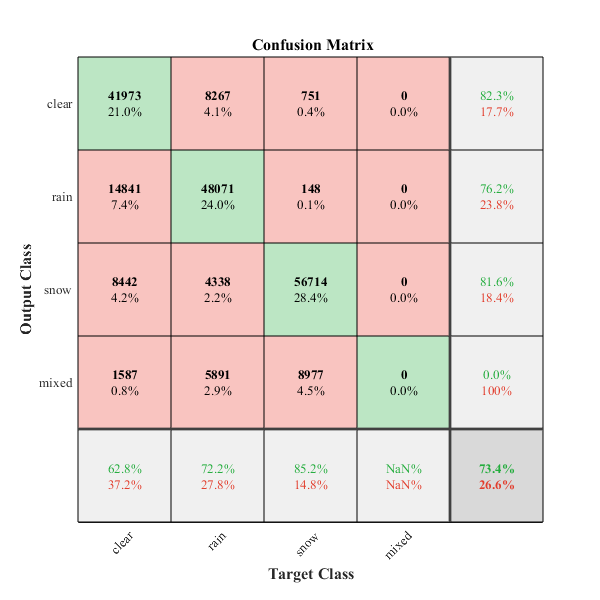

clear
load net_rgs_rain.mat
load net_rgs_snow.mat
load Dic_DPR_ocean_small.mat
Inputs = ["TB10v","TB10h","TB18v","TB18h","TB23v","TB37v","TB37h",....
          "TB89v","TB89h","TB166v","TB166h","TB183v","TB183h",...
          "LWP","IWP","T2m","WVP","CAPE"];

X_test =  data.test(:,Inputs);
X_test =  table2array(X_test);
YTest_c = data.test.Phase;
YTest_r = data.test.Rate;

% making predictions by the networks
YPred_rain = predict(net_rgs_rain,X_test);
YPred_snow = predict(net_rgs_snow,X_test);


YPred_c = strings(size(YTest_c));
YPred_c(YPred_rain>0) = "rain";
YPred_c(YPred_snow>0) = "snow";
YPred_c(YPred_rain>0 & YPred_snow>0) = "mixed";
YPred_c(YPred_rain==0 & YPred_snow==0) = "clear";

YPred_r = zeros(size(YTest_r));

for i=1:length(YPred_r)
    if YPred_c(i) == "rain"
        YPred_r(i) = YPred_rain(i);
    elseif YPred_c(i) == "snow"
        YPred_r(i) = YPred_snow(i);
    elseif YPred_c(i) == "mixed"
        YPred_r(i) = (YPred_rain(i) + YPred_snow(i))/2;
    else
        YPred_r(i)= 0;
    end
end
plotconfusion(categorical(YTest_c),categorical(YPred_c))
set(gca,'fontname','times')
set(findobj(gca,'type','text'),'fontname','times') 


idx_rain = YPred_c=="rain" & YTest_c=="rain";
idx_snow = YPred_c=="snow" & YTest_c=="snow";

error.rain = YPred_r(idx_rain) - YTest_r(idx_rain);
error.snow = YPred_r(idx_snow) - YTest_r(idx_snow);

bias.rain = mean(error.rain);
mae.rain  = mean(abs(error.rain));
rmse.rain = sqrt(mean((error.rain).^2));

Tabstats.rain  = array2table([bias.rain,mae.rain,rmse.rain],'VariableNames',{'rain_bias','rain_mae','rain_rmse'});

Tabstats.rain

ans = 1×3 table
    rain_bias    rain_mae    rain_rmse
    _________    ________    _________

    -0.078519     1.3891      4.4509  


bias.snow = mean(error.snow);
mae.snow  = mean(abs(error.snow));
rmse.snow  = sqrt(mean((error.snow).^2));
Tabstats.snow  = array2table([bias.snow,mae.snow,rmse.snow],'VariableNames',{'snow_bias','snow_mae','snow_rmse'});
Tabstats.snow

ans = 1×3 table
    snow_bias    snow_mae    snow_rmse
    _________    ________    _________

    -0.061988    0.22261      0.33798 


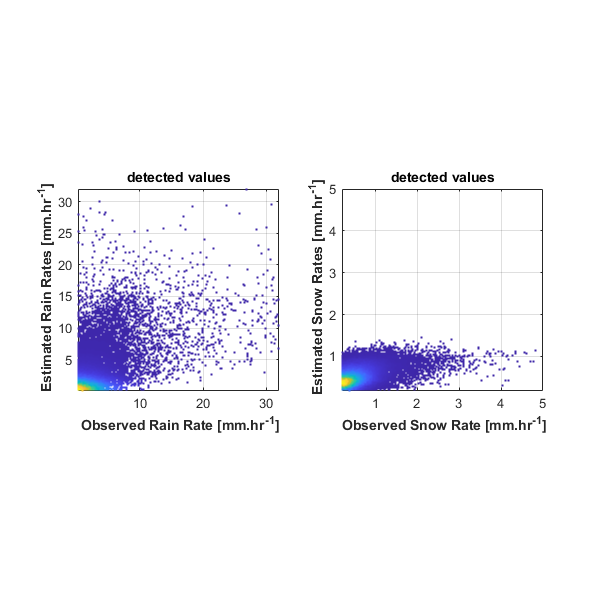


subplot 121
dscatter(YTest_r(idx_rain),YPred_r(idx_rain),'BINS',[1000,1000])
xlabel('\bf Observed Rain Rate [mm.hr^{-1}]')
ylabel('\bf Estimated Rain Rates [mm.hr^{-1}]')
xlim([0.2 32]); ylim([0.2 32])
title('detected values')
axis square; grid on; box on;
subplot 122
dscatter(YTest_r(idx_snow),YPred_r(idx_snow),'BINS',[1000,1000])
xlabel('\bf Observed Snow Rate [mm.hr^{-1}]')
ylabel('\bf Estimated Snow Rates [mm.hr^{-1}]')
xlim([0.2 5]); ylim([0.2 5])
title('detected values')
axis square; grid on; box on;

## 4- Feature Space Retriavals using Focal Loss 

clear
load Dic_DPR_ocean_small.mat
Inputs = ["TB10v","TB10h","TB18v","TB18h","TB23v","TB37v","TB37h",....
          "TB89v","TB89h","TB166v","TB166h","TB183v","TB183h",...
          "LWP","IWP","T2m","WVP","CAPE"];
nbins = 10;
edges.snow = logspace(log10(0.19),log10(2),nbins);
edges.snow = [edges.snow, 32];

edges.rain = logspace(log10(0.19),log10(16),nbins);
edges.rain = [edges.rain, 300];

% snowfall data
X_train_s  = data.train(data.train.Phase=="snow",Inputs);
Y_train_s  = data.train(data.train.Phase=="snow","Rate");    
Y_train_sc = discretize(Y_train_s.Rate,edges.snow);
Y_train_sc = categorical(Y_train_sc);

X_val_s  = data.val(data.val.Phase=="snow",Inputs);
Y_val_s  = data.val(data.val.Phase=="snow","Rate");    
Y_val_sc = discretize(Y_val_s.Rate,edges.snow);
Y_val_sc = categorical(Y_val_sc);

X_test_s  = data.test(data.test.Phase=="snow",Inputs);
Y_test_s  = data.test(data.test.Phase=="snow","Rate");    
Y_test_sc = discretize(Y_test_s.Rate,edges.snow);
Y_test_sc = categorical(Y_test_sc);

% rainfall data
X_train_r  = data.train(data.train.Phase=="rain",Inputs);
Y_train_r  = data.train(data.train.Phase=="rain","Rate");    
Y_train_rc = discretize(Y_train_r.Rate,edges.rain);
Y_train_rc = categorical(Y_train_rc);

X_val_r  = data.val(data.val.Phase=="rain",Inputs);
Y_val_r  = data.val(data.val.Phase=="rain","Rate");    
Y_val_rc = discretize(Y_val_r.Rate,edges.rain);
Y_val_rc = categorical(Y_val_rc);

X_test_r  = data.test(data.test.Phase=="rain",Inputs);
Y_test_r  = data.test(data.test.Phase=="rain","Rate");    
Y_test_rc = discretize(Y_test_r.Rate,edges.rain);
Y_test_rc = categorical(Y_test_rc);

numClasses.snow = length(unique(Y_train_sc));
numClasses.rain = length(unique(Y_train_rc));

% converting tables to array for traning the DNN
X_train_s = table2array(X_train_s); X_val_s = table2array(X_val_s);

net_mclas_snow = MLP_PMW_FL(numClasses.snow,X_train_s,Y_train_sc,X_val_s,Y_val_sc);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 2).



% converting tables to array for traning the DNN
X_train_r = table2array(X_train_r); X_val_r = table2array(X_val_r);

net_mclas_rain = MLP_PMW_FL(numClasses.rain,X_train_r,Y_train_rc,X_val_r,Y_val_rc);

YPredTest.snow = classify(net_mclas_snow,X_test_s);
YPredTest.rain = classify(net_mclas_rain,X_test_r);

%plotconfusion(Y_test_sc,YPredTest.snow)
%plotconfusion(Y_test_rc,YPredTest.rain)
save(['net_mclas_FL',num2str(nbins),'.mat'],'net_mclas_snow','net_mclas_rain');

## 5- Localizing the DNN Retriavals

clear

load Dic_DPR_ocean_small.mat
load net_mclas_FL10.mat
load net_mcls_CE.mat 
Inputs = ["TB10v","TB10h","TB18v","TB18h","TB23v","TB37v","TB37h",....
          "TB89v","TB89h","TB166v","TB166h","TB183v","TB183h",...
          "LWP","IWP","T2m","WVP","CAPE"];

XTest   =  data.test(:,Inputs);
XTest   =  table2array(XTest);
YTest_c =  data.test.Phase;

YPred_c = classify(net_CE,XTest);

idx_snow = (YPred_c == "snow");


idx_rain = (YPred_c == "rain");

% snowfall training data
XTrain_s  = data.train(data.train.Phase=="snow",Inputs); 
XTrain_s  = table2array(XTrain_s);
YTrain_s  = data.train.Rate(data.train.Phase=="snow");

XTest_s  = data.test(data.test.Phase=="snow",Inputs); 
XTest_s  = table2array(XTest_s);
YTest_s  = data.test.Rate(data.test.Phase=="snow");

% rainfall training data
XTrain_r  = data.train(data.train.Phase=="rain",Inputs); 
XTrain_r  = table2array(XTrain_r);
YTrain_r  = data.train.Rate(data.train.Phase=="rain");

XTest_r  = data.test(data.test.Phase=="rain",Inputs); 
XTest_r  = table2array(XTest_r);
YTest_r  = data.test.Rate(data.test.Phase=="rain");

%---
layer = 'fc_3';

XTrain_rain_features = activations(net_mclas_rain,XTrain_r,layer,'OutputAs','rows');
XTest_rain_features  = activations(net_mclas_rain,XTest_r,layer,'OutputAs','rows');

XTrain_snow_features = activations(net_mclas_snow,XTrain_s,layer,'OutputAs','rows');
XTest_snow_features  = activations(net_mclas_snow,XTest_s,layer,'OutputAs','rows');

Idx_r = knnsearch(XTrain_rain_features,XTest_rain_features,'k',25);
Idx_s = knnsearch(XTrain_snow_features,XTest_snow_features,'k',25);


YTestPred_rain_rate = zeros(length(XTest_rain_features),1);
YTestPred_snow_rate = zeros(length(XTest_snow_features),1);

for i = 1:length(YTestPred_rain_rate)

    YTestPred_rain_rate(i,:) = mean(YTrain_r(Idx_r(i,:)));

end

for i = 1:length(YTestPred_snow_rate)

    YTestPred_snow_rate(i,:) = mean(YTrain_s(Idx_s(i,:)));

end

error.snow = YTestPred_snow_rate-YTest_s;
error.rain = YTestPred_rain_rate-YTest_r;

bias.snow = mean(error.snow);
mae.snow  = mean(abs(error.snow));
rmse.snow = sqrt(mean((error.snow).^2));
Tabstats.snow = array2table([bias.snow,mae.snow,rmse.snow],'VariableNames',{'bias','mae','rmse'})

Tabstats = struct with fields:
    snow: [1×3 table]


Tabstats.snow

ans = 1×3 table
       bias          mae       rmse  
    ___________    _______    _______

    -0.00075484    0.21927    0.33714



bias.rain = mean(error.rain);
mae.rain  = mean(abs(error.rain));
rmse.rain = sqrt(mean((error.rain).^2));
Tabstats.rain = array2table([bias.rain,mae.rain,rmse.rain],'VariableNames',{'bias','mae','rmse'})

Tabstats = struct with fields:
    snow: [1×3 table]
    rain: [1×3 table]


Tabstats.rain

ans = 1×3 table
      bias       mae       rmse 
    ________    ______    ______

    0.021868    1.0018    3.7402


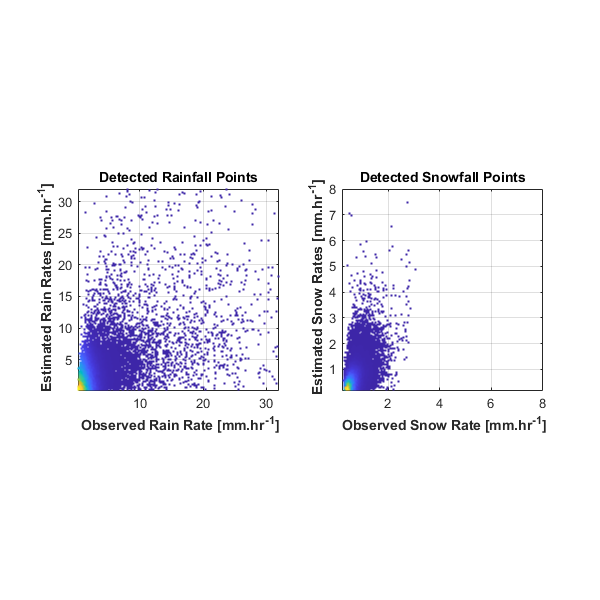

subplot 121
dscatter(YTestPred_rain_rate,YTest_r,'BINS',[1000,1000])
xlabel('\bf Observed Rain Rate [mm.hr^{-1}]')
ylabel('\bf Estimated Rain Rates [mm.hr^{-1}]')
xlim([0.2 32]); ylim([0.2 32])
title('Detected Rainfall Points')
axis square; grid on; box on;

subplot 122
dscatter(YTestPred_snow_rate,YTest_s,'BINS',[1000,1000])
xlabel('\bf Observed Snow Rate [mm.hr^{-1}]')
ylabel('\bf Estimated Snow Rates [mm.hr^{-1}]')
xlim([0.2 8]); ylim([0.2 8])
title('Detected Snowfall Points')
axis square; grid on; box on;